# Plots

Laby Nicolas & Van Mechelen Alex

clc, clearvars
set(groot,'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(groot,'defaultLegendLocation','best')

# Basic Q-value algorithm

## 1 Example

exploration function = IdentityExplorationMethod

reward = loss*-100 + (number_of_completed_rows+above_row_completion)*500;

**float** gamma = 0.80f;*        // Discount factor*

**float** alpha = 0.02f;*        // Learning rate*

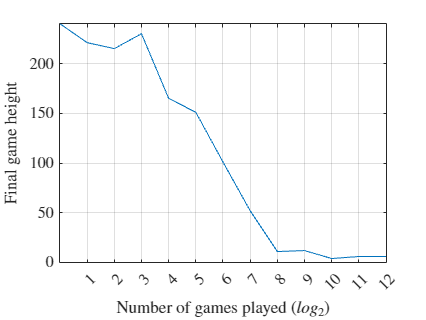

data1 = [1, 240, 0, 767
2, 221, 0, 1459
4, 215, 0, 2786
8, 230, 0, 5204
16, 165, 0, 9577
32, 151, 0, 16860
64, 101, 0, 28223
128, 52, 0, 44725
256, 11, 0, 66402
512, 12, 0, 91524
1024, 4, 0, 114256
2048, 6, 0, 134693
4096, 6, 0, 152489
8192, 4, 0, 166913];

subplot
plot(log2(data1(:,1)), data1(:,2))
grid on
xlabel("Number of games played ($log_2$)")
ylabel("Final game height")
xticks(1:12)
axis([0 12 0 max(data1(:,2))])

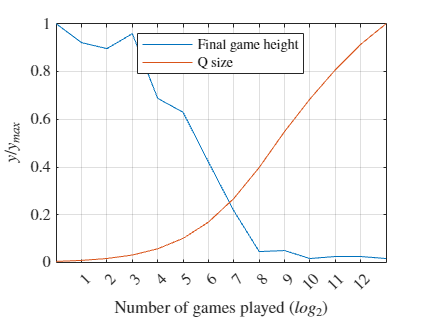


plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
%plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
%legend("Final game height", "Epsilon", "Q size")
legend("Final game height", "Q size")
xticks(1:12)
axis([0 13 0 1])

## 2 Play with reward function

The following metrics are used to calculate the reward function:

- loss (*Number of rows added to height when they're 'pushed down')*

- completed rows (number_of_completed_rows+above_row_completion)

- hole density

- bumpiness

reward = k_loss*loss + k_comp*(number_of_completed_rows+above_row_completion)

Everytime we can play with the coefficients associated to a metric

### 1 Play with loss & completed rows

The final metric will be the final/lowest height achieved after 2^11 games (not 2^13 for computation reasons)

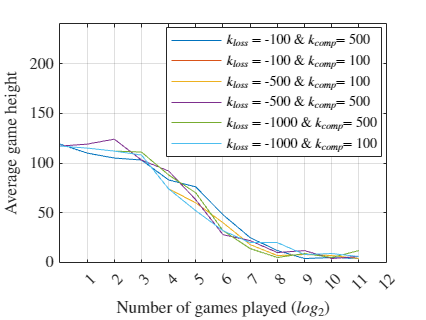

data1 = [1 240 0 767 119
2 221 0 1459 110
4 215 0 2786 105
8 230 0 5204 103
16 165 0 9577 83
32 151 0 16860 76
64 101 0 28223 48
128 35 0 44714 25
256 21 0 66138 12
512 5 0 91211 4
1024 4 0 114578 5
2048 2 0 135171 4]; % k_loss = -100 & k_comp = 500

data2 = [1 234 0 749 117
2 234 0 1456 119
4 256 0 2784 124
8 195 0 5214 103
16 187 0 9597 92
32 138 0 16945 63
64 46 0 28378 28
128 44 0 45087 22
256 14 0 66362 10
512 22 0 91248 12
1024 2 0 114415 4
2048 5 0 135733 6]; % k_loss = -100 & k_comp = 100

data3 = [1 234 0 771 117
2 233 0 1492 115
4 226 0 2818 112
8 209 0 5303 108
16 155 0 9735 74
32 120 0 17081 60
64 83 0 28579 40
128 51 0 45085 18
256 10 0 66538 7
512 13 0 91651 8
1024 10 0 114908 7
2048 8 0 135470 4
]; % k_loss = -500 & k_comp = 100

data4 = [1 234 0 749 117
2 234 0 1456 119
4 256 0 2784 124
8 195 0 5214 103
16 187 0 9597 92
32 138 0 16945 63
64 46 0 28378 28
128 44 0 45087 22
256 14 0 66362 10
512 22 0 91248 12
1024 2 0 114415 4
2048 5 0 135733 6]; % k_loss = -500 & k_comp = 500

data5 = [1 234 0 771 117
2 233 0 1492 115
4 226 0 2818 112
8 220 0 5322 111
16 169 0 9759 88
32 147 0 17163 70
64 68 0 28687 32
128 27 0 45292 14
256 11 0 66763 5
512 9 0 91922 9
1024 5 0 115040 5
2048 14 0 135846 12]; % k_loss = -1000 & k_comp = 500

data6 = [1 234 0 771 117
2 233 0 1492 115
4 226 0 2818 112
8 209 0 5303 108
16 155 0 9735 74
32 102 0 17025 52
64 76 0 28613 32
128 23 0 45113 20
256 22 0 66161 20
512 11 0 91229 8
1024 23 0 114497 9
2048 4 0 135744 6]; % k_loss = -1000 & k_comp = 100

data = zeros(12,5,2);
data(:,:,1) = data1;
data(:,:,2) = data2;
data(:,:,3) = data3;
data(:,:,4) = data4;
data(:,:,5) = data5;
data(:,:,6) = data6;

subplot
for i = 1:size(data,3)
    plot(log2(data(:,1,i)), data(:,5,i))
    hold on
end
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("Average game height")
xticks(1:12)
axis([0 12 0 max(data1(:,2))])
legend("$k_{loss}$ = -100 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -100 \& $k_{comp}$= 100", ...
    "$k_{loss}$ = -500 \& $k_{comp}$= 100", ...
    "$k_{loss}$ = -500 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -1000 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -1000 \& $k_{comp}$= 100")

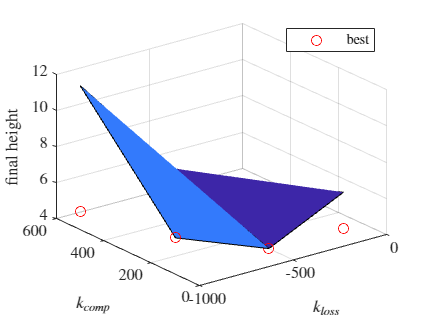


x = [-1000 -500 -100];
y = [100 500];
z = [data6(end,5) data3(end,5) data2(end,5); data5(end,5) data4(end,5) data1(end,5)];
%z2 = [min(data3(:,2)) min(data2(:,2)); min(data4(:,2)) min(data1(:,2))];
x2 = [-100 -100 -500 -500 -1000 -1000];
y2 = [500 100 100 500 500 100];
z2 = [min(data1(:,5)) min(data2(:,5)) min(data3(:,5)) min(data4(:,5)), min(data5(:,5)), min(data6(:,5))];
surf(x,y,z)
hold on
plot3(x2,y2,z2, 'ro')
hold off
xlabel("$k_{loss}$")
ylabel("$k_{comp}$")
zlabel("final height")
legend("", "best")

### 2 Play with hole density & bumpiness

(...)

## 3 Play with discount factor and learning rate

(...)

## 4 Performance metric

Final height vs evolution during the game

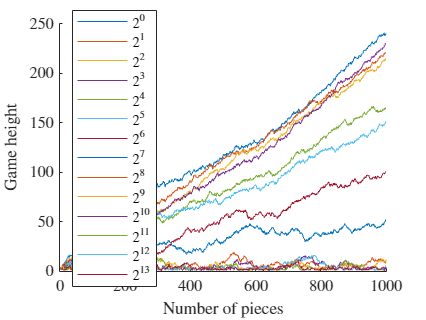

% load heights.txt
log_data = importdata('heights.txt');

figure
hold on
legend_str = cell(1, ceil(log2(size(log_data, 1))));
for i = 1:size(log_data, 1)
    if ~bitand(i, i-1) %if a power of two
        max_i = i;
        plot(1:length(log_data(i,:)),log_data(i,:))
        legend_str{log2(i)+1} = ['$2^{' num2str(log2(i)) '}$'];
    end
end
hold off

legend(legend_str(~cellfun('isempty',legend_str)))
xlabel('Number of pieces')
ylabel('Game height')

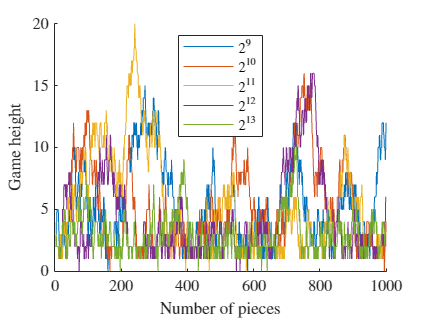


% mean and variance

mean_data = zeros(max_i,1);
var_data= zeros(max_i,1);

for i = 1:size(log_data, 1)
    mean_data(i) = mean(log_data(i,:));
    var_data(i) = var(log_data(i,:));
end

%last 5 powers of 2

figure
hold on
legend_str = cell(1, ceil(log2(size(log_data, 1))));
for i = 1:size(log_data, 1)
    if ~bitand(i, i-1) && i>2^(13-5) %if a power of two
        plot(1:length(log_data(i,:)),log_data(i,:))
        legend_str{log2(i)+1} = ['$2^{' num2str(log2(i)) '}$'];
    end
end
hold off

legend(legend_str(~cellfun('isempty',legend_str)))
xlabel('Number of pieces')
ylabel('Game height')

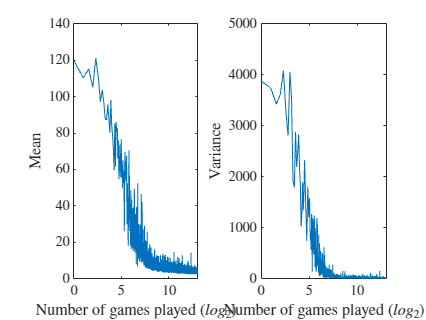


% hold on
% for i = 1:size(log_data, 1)
%     if ~bitand(i, i-1) && i>2^(13-5) %if a power of two
%         plot([1 length(log_data(i,:))], [mean_data(i) mean_data(i)], '--')
%     end
% end
% hold off

% plot((1:size(log_data, 1)), mean_data)
% ylabel("Mean")
% xlabel("Number of games played")
% 
% plot((1:size(log_data, 1)), var_data)
% ylabel("Variance")
% xlabel("Number of games played")

subplot(1,2,1)
plot(log2(1:size(log_data, 1)), mean_data)
ylabel("Mean")
xlabel("Number of games played ($log_2$)")
subplot(1,2,2)
plot(log2(1:size(log_data, 1)), var_data)
xlabel("Number of games played ($log_2$)")
ylabel("Variance")

# Discussion over the exploration method

For the following discussion we will always use the following cost function and parameters:

reward = loss*-100 + (number_of_completed_rows+above_row_completion)*500;

**float** gamma = 0.80f;*        // Discount factor*

**float** alpha = 0.02f;*        // Learning rate*

## 1 Random exploration method

exploration function = RandomExplorationMethod

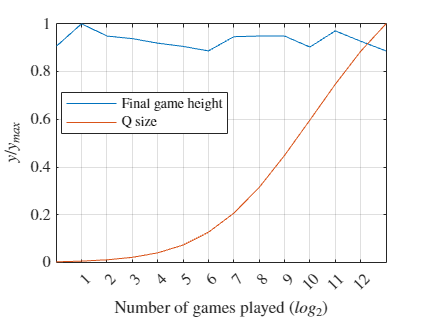

data1 = [1, 334, 0, 803
2, 369, 0, 1595
4, 350, 0, 3137
8, 346, 0, 5979
16, 339, 0, 11252
32, 334, 0, 20314
64, 327, 0, 35218
128, 349, 0, 57371
256, 350, 0, 87427
512, 350, 0, 124718
1024, 333, 0, 165909
2048, 358, 0, 207577
4096, 342, 0, 245911
8192, 327, 0, 278052];

figure
plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
%plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
%legend("Final game height", "Epsilon", "Q size")
legend("Final game height", "Q size")
xticks(1:12)
axis([0 13 0 1])

## 2 Epsilon greedy exploration method

### 1 Basic

epsilon = 0.1 and no decay

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))

Index in position 2 exceeds array bounds.

hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")


### 2 Play with epsilon

epsilon = 0:0.1:0.9 and no decay

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")


### 3 Play with decay

epsilon = 0.1 and decay 

`if`` (``EPSILON` `>` `0.001``) ``EPSILON` `*=` `0.99``; ``else` `EPSILON` `=` `0`

data1 = [1 250 0.1 800 122
2 250 0.099 1499 125
4 250 0.0970299 2855 128
8 241 0.0932065 5384 119
16 184 0.0860058 9841 92
32 125 0.0732303 17474 61
64 128 0.0530906 29537 70
128 33 0.0279042 46983 19
256 36 0.00770858 69435 13
512 7 0 94554 5
1024 11 0 117495 4
2048 2 0 137197 4
4096 4 0 154878 3
8192 9 0 169316 4];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
plot(log2(data1(:,1)), data1(:,5)./max(data1(:,5)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size", "Average game height")

## 3 Simple exploration method

### 1 Basic

 **int** N_MAX = 10;

 **double** R_PLUS = 20.0;

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")

### 2 Play with Nmax & Rplus

(...)

# Computing time, convergence rate, stability, ...

(...)